# Introduction: PID control

## PID control

% pid controller object
kp = 1;
ki = 1;
kd = 1;
C = pid(kp,ki,kd);

**Example: 2nd order mass-spring-damper system**

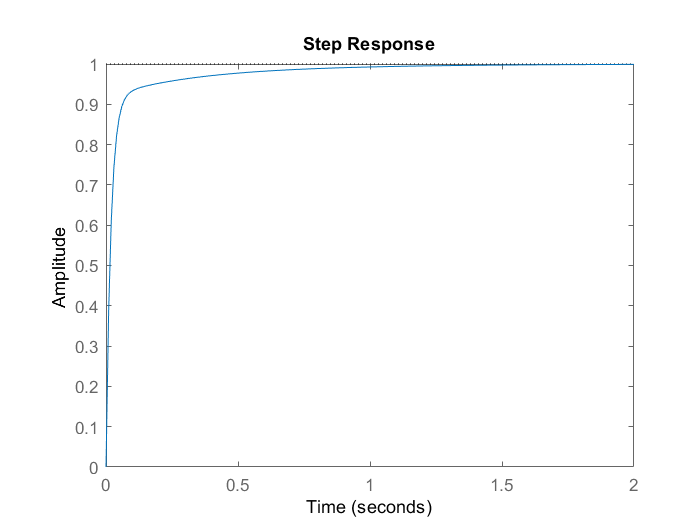

% 2nd order mass-spring-damper system
m = 1;
b = 10;
k = 20;
s = tf('s');
G = 1/(m*s^2 + b*s + k);

Kp = 300;
Ki = 400;
Kd = 50;
C = pid(Kp, Ki, Kd);
T = feedback(C*G, 1);
t = 0:0.01:2;
step(T,t)

**Automatic PID Tuning**

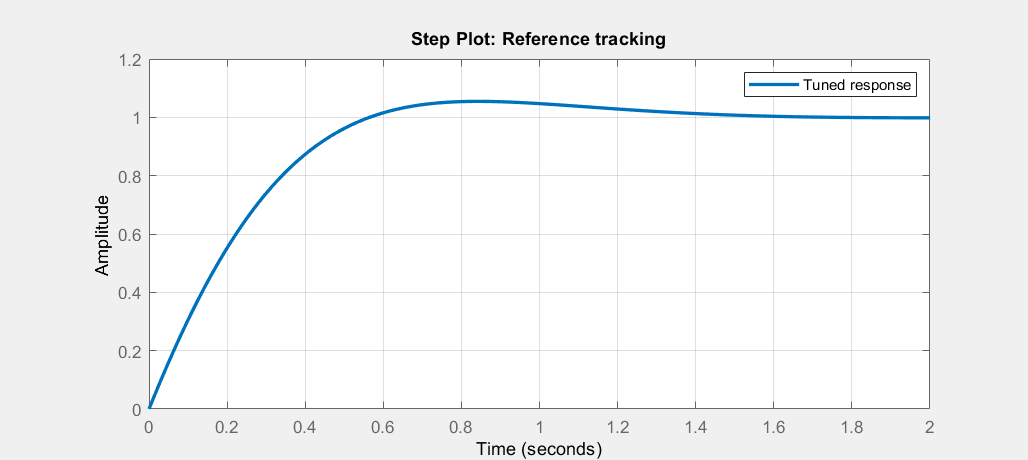

% call pidtuner
pidTuner(G, 'pid');

% pid baseline 
pidTuner(G, C);

% in frequency domain
opts = pidtuneOptions('CrossoverFrequency',32,'PhaseMargin',90);
[C, info] = pidtune(G, 'pid', opts)


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 320, Ki = 796, Kd = 32.2
 
Continuous-time PID controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 32
           PhaseMargin: 90
